%Create a .mat file for saving data
foldernam = "Evolution - Praful\"

foldernam = "Evolution - Praful\"

filnam = foldernam +  "1_CCRN_1_cat"

filnam = "Evolution - Praful\1_CCRN_1_cat"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat"


load(foldernam + 'Data\' + model_nam + '_Ham.mat')
load(foldernam + 'Data\' + model_nam + '_hcnet.mat')

savenam = foldernam + 'Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat"

load(savenam)
PS_traj_21 = PS_traj;
savenam = foldernam + 'Data\1-CCRN-1-cat_descend_3_1_straightIC_500_05-Dec-2023.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_3_1_straightIC_500_05-Dec-2023.mat"

load(savenam)
PS_traj_31 = PS_traj;

## Descent summary


[traj_pts,num_spec] = size(traj);

init_iter = 1;
tot_iter = size(S_arr,1);

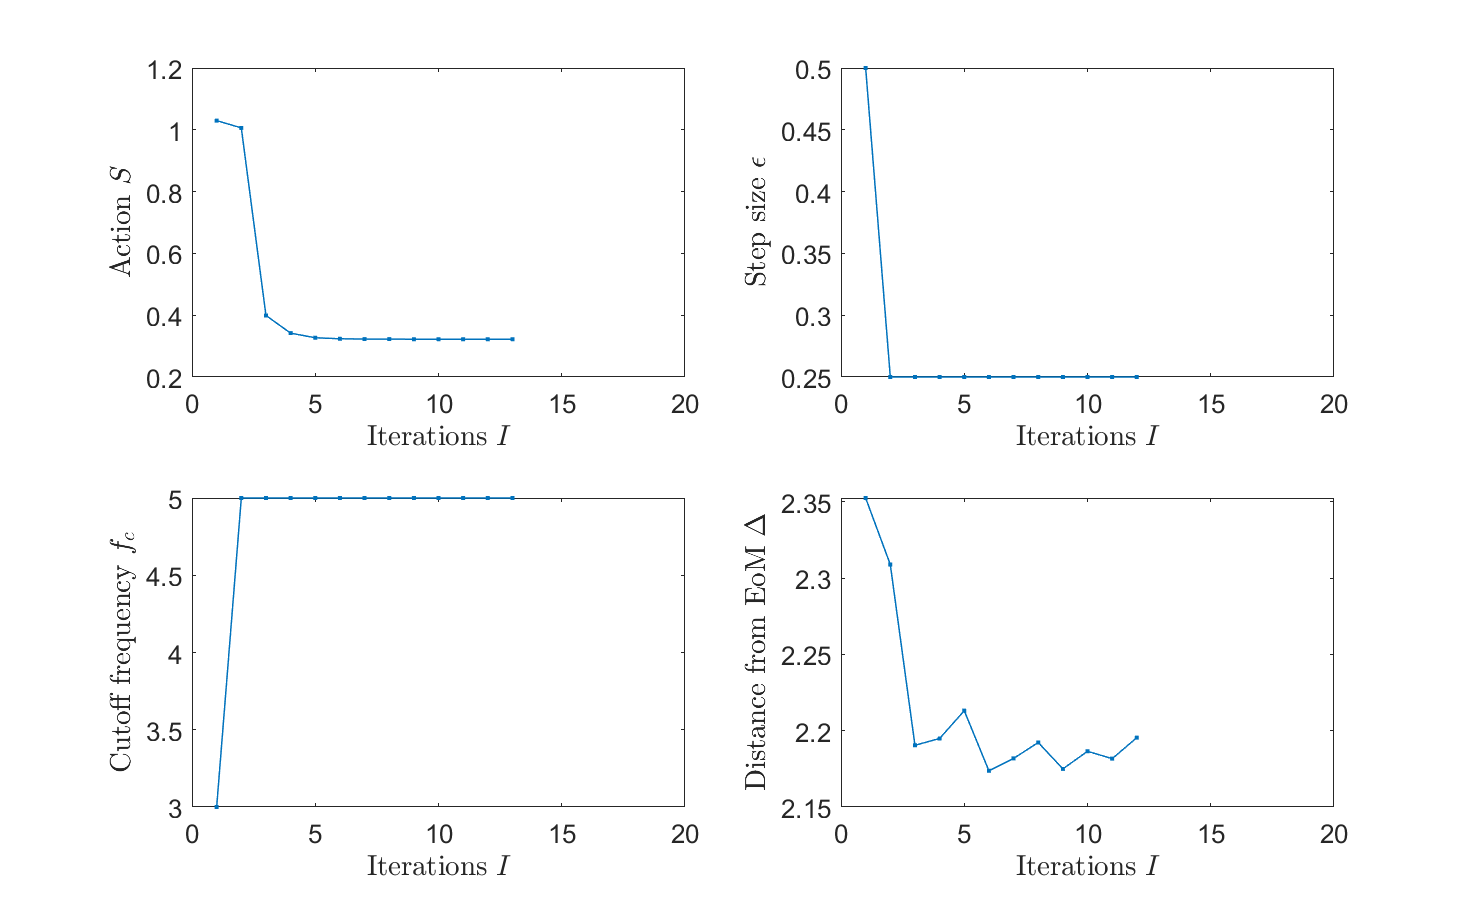


%Action
figure()
subplot(2,2,1)
plot(S_arr,'.-','LineWidth',0.75)
ylabel('Action $S$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%epsilon-step size
subplot(2,2,2)
plot(eps_arr,'.-','LineWidth',0.75)
ylabel('Step size $\epsilon$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%cutoff frequency bin
subplot(2,2,3)
plot(f0_arr,'.-','LineWidth',0.75)
ylabel('Cutoff frequency $f_c$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;


%Ham EoM distance frequency bin
subplot(2,2,4)
plot(a_arr,'.-','LineWidth',0.75)
ylabel('Distance from EoM $\Delta$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

x0=0.1;
y0=0.1;
width=26;
height=16;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])

save_plot_name = save_plot_name_root + '_action_eps_freq_delta.png';

Unrecognized function or variable 'save_plot_name_root'.

saveas(gcf,save_plot_name)

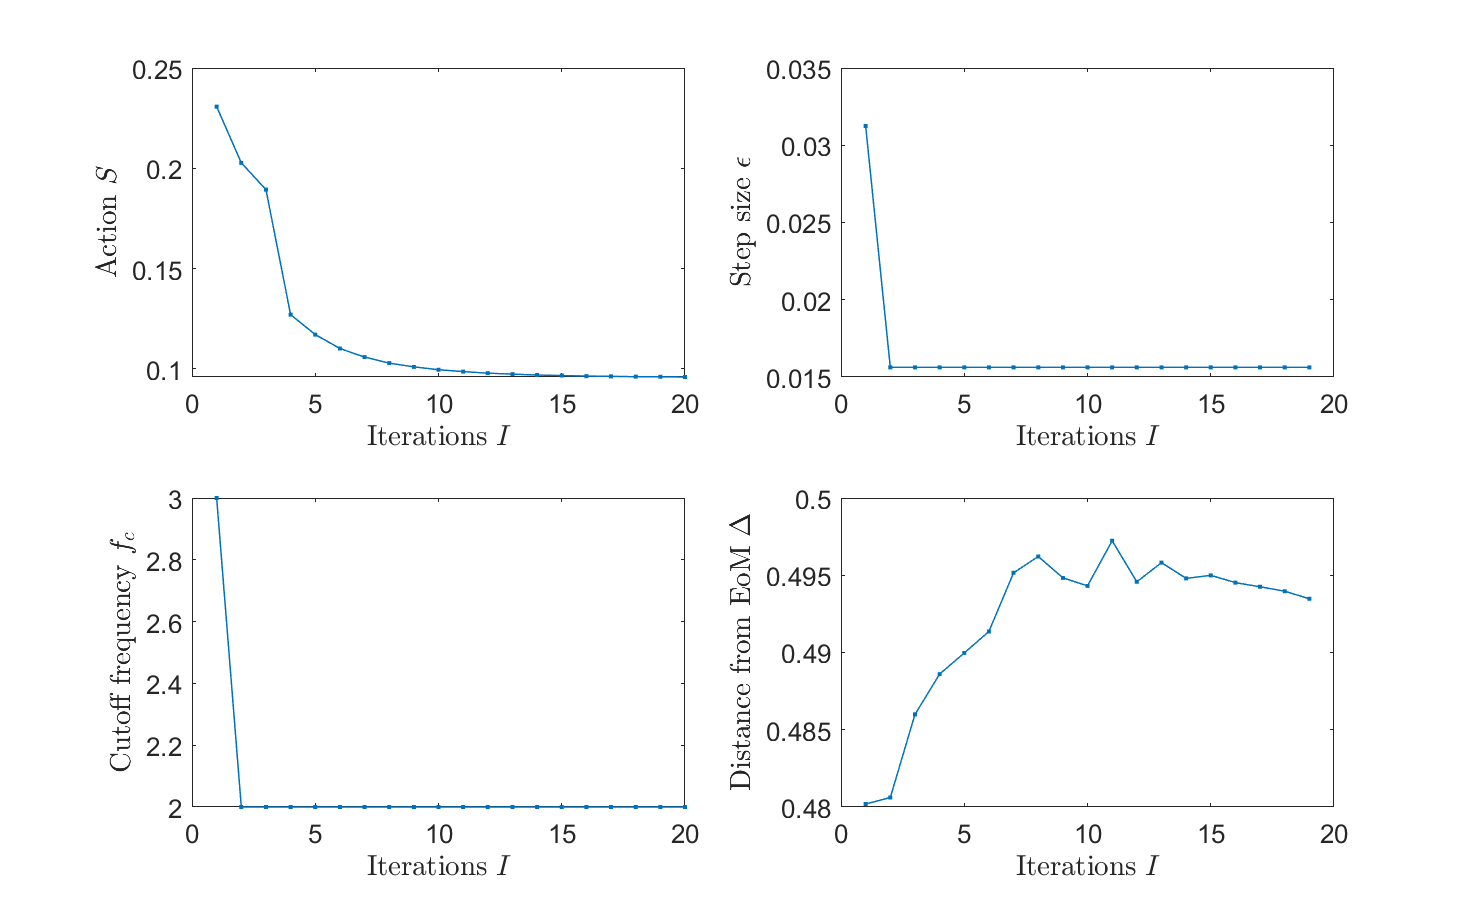


%Action
figure()
subplot(2,2,1)
plot(S_arr,'.-','LineWidth',0.75)
ylabel('Action $S$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%epsilon-step size
subplot(2,2,2)
plot(eps_arr,'.-','LineWidth',0.75)
ylabel('Step size $\epsilon$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%cutoff frequency bin
subplot(2,2,3)
plot(f0_arr,'.-','LineWidth',0.75)
ylabel('Cutoff frequency $f_c$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;


%Ham EoM distance frequency bin
subplot(2,2,4)
plot(a_arr,'.-','LineWidth',0.75)
ylabel('Distance from EoM $\Delta$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

x0=0.1;
y0=0.1;
width=26;
height=16;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])

save_plot_name = save_plot_name_root + '_action_eps_freq_delta.png';

Unrecognized function or variable 'save_plot_name_root'.

saveas(gcf,save_plot_name)

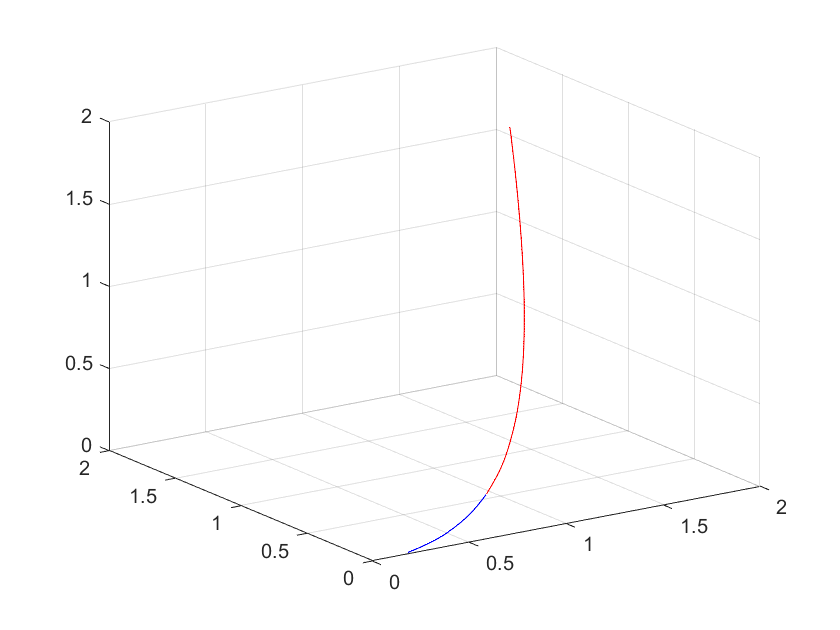

figure()
PS_traj = PS_traj_21;
plot3(PS_traj(:,1),PS_traj(:,2),PS_traj(:,3),'b')
hold on
PS_traj = PS_traj_31;
plot3(PS_traj(:,1),PS_traj(:,2),PS_traj(:,3),'r')
hold off
grid on

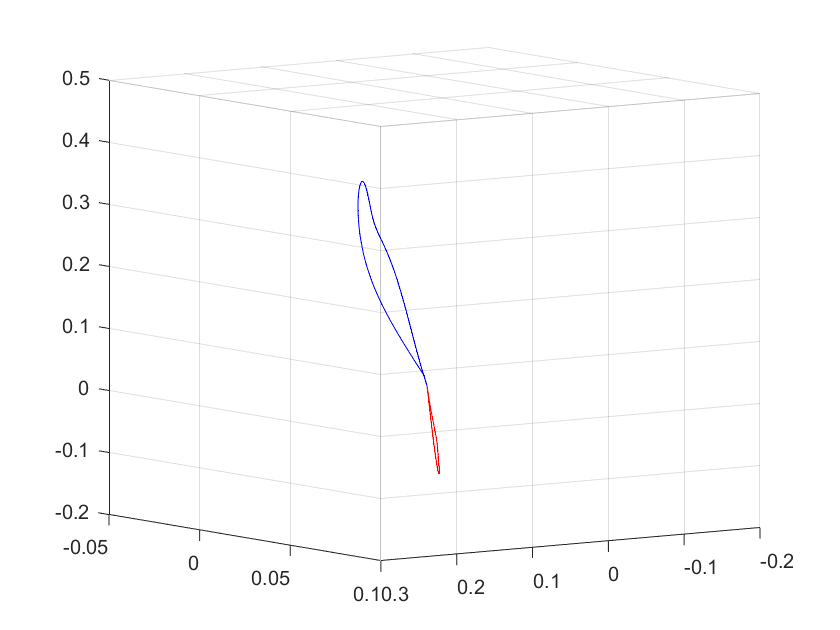

figure()
PS_traj = PS_traj_21;
plot3(PS_traj(:,4),PS_traj(:,5),PS_traj(:,6),'b')
hold on
PS_traj = PS_traj_31;
plot3(PS_traj(:,4),PS_traj(:,5),PS_traj(:,6),'r')
hold off
grid on

## Progress in phase space

init_iter = 1;
tot_iter = 7;

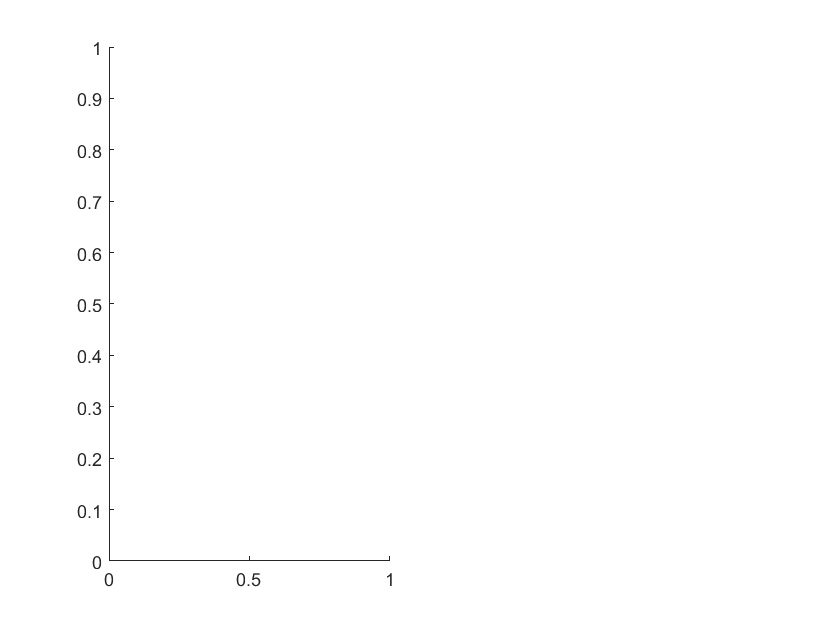

%Trajectories
lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));
diter  = 1;
figure()
subplot(1,2,1)
hold on

for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    traj = PS_traj(:,1:num_spec);
    plot(traj(:,1),traj(:,2:end),'color',blueGRADIENTflexible(i,tot_iter))
end

'picker_arr_idx' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\prafu\OneDrive\Desktop\AFGD\Descender-for-CRN-escapes

Change the MATLAB current folder or add its folder to the MATLAB path.

xlabel('$q_1$','interpreter','latex','FontSize',20)
ylabel('$q_2$','interpreter','latex','FontSize',20)
title(plotnam+' descent','interpreter','latex','FontSize',20)
hold off
%grid on

%momentum
subplot(1,2,2)
hold on
for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    traj = PS_traj(:,num_spec + 1:2*num_spec);
    plot(traj(:,1),traj(:,2:end),'color',blueGRADIENTflexible(i,tot_iter))
end
ax=gca;
ax.FontSize = 13;
xlabel('$p_1$','interpreter','latex','FontSize',20)
ylabel('$p_2$','interpreter','latex','FontSize',20)
title("Progress: light to dark",'interpreter','latex','FontSize',20)
hold off

%grid on
x0=0.1;
y0=0.1;
width=28;
height=8;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = save_plot_name_root + '_descender_progress.png';
saveas(gcf,save_plot_name)


## Plot sudden jump gradients 

### Find spots

%Find index of sudden jumps of S_arr
%[TF,S1] = ischange(S_arr,'variance','MaxNumChanges',10);
TF = findchangepts(S_arr','MaxNumChanges',4);
 TF = [TF 45 size(S_arr,1)];

figure()
plot(S_arr)
hold on
xran = 1:size(S_arr,1);
plot(xran(TF),S_arr(TF),'*')
hold off

### Plot gradient

figure()
subplot(1,2,1)
for i = 1:size(TF,2)
    iter = TF(i);
    g_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,iter);
    plot(g_s(:,2),'DisplayName','I='+string(iter),'LineWidth',1.5)
    hold on
end
%grid on
xlabel('Point along curve','Interpreter','latex','FontSize',20)
ylabel('$\delta q_2$ smooth $\equiv g_{s2}$','Interpreter','latex','FontSize',20)
legend('location','best')
%title(plotnam + ' : dim #2')
hold off
%xlim([0 500])

subplot(1,2,2)
for i = 1:size(TF,2)
    iter = TF(i);
    g_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,iter);
    semilogy(abs(fft(g_s(:,2))).^2,'DisplayName','f_0='+string(f0_arr(iter)),'LineWidth',1.5)
    xlim([0 20])
    hold on
end
%grid on
%title('Descent progress')
xlabel('Frequency','Interpreter','latex','FontSize',20)
ylabel('Power','Interpreter','latex','FontSize',20)
legend('location','best')
hold off


x0=0.1;
y0=0.1;
width=28;
height=8;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = save_plot_name_root + '_g_s_change_2.png';

saveas(gcf,save_plot_name)

plotnam_old = plotnam;

TF = [183 212]

### Hamilton's EoM

for i = 1:size(TF,2)
    iter = TF(i);
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,iter);
    t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
    save_plot_name = save_plot_name_root + '_HamEoM_'+string(iter)+'.png';
    plotnam = string(iter);
    Ham_closest_approach(PS_traj,S_traj,t_traj,...
    dHamdp_fun, dHamdq_fun, save_plot_name,1,plotnam)
    
end
plotnam = plotnam_old;

save('PS_traj_schlogl_2.mat',"PS_traj")

action_PS_traj(PS_traj)

## Surf plots

%Surf plots
%Points to skip along trajectory
dtraj = 10;
diter = 2;

traj_pts_indx = 1000;
tot_iter = 83;
init_iter = 1;
%deltax
[deltax_3d, deltax_3d_fft] = surf_input(deltax_arr,num_spec,tot_iter,traj_pt_arr,traj_pts_indx);
[deltax_s_3d, deltax_s_3d_fft] = surf_input(deltax_lp_arr,num_spec,tot_iter,traj_pt_arr,traj_pts_indx);

for i = 1:num_spec
    figure()
    surf(squeeze(deltax_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations (skip every '+string(diter)+')')
    ylabel('Normalized Trajectory')

    figure()
    surf(squeeze(deltax_s_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x smooth : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Normalized Trajectory')

    figure()
    surf(squeeze(deltax_3d_fft(i,1:20,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x fft: dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Normalized Trajectory')

    figure()
    surf(squeeze(deltax_s_3d_fft(i,1:20,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x smooth fft : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Normalized Trajectory')

end

%Plot delta_x^2
delta_S = zeros(tot_iter,1);
for i = 1:tot_iter
    delta_S(i) = sum(squeeze(deltax_3d(:,:,i)).*squeeze(deltax_s_3d(:,:,i)),"all");
end
figure()
semilogy(delta_S,'.-')
title('\delta x*\delta x_s')

%Plot delta_x_s^2
delta_S = zeros(tot_iter,1);
for i = 1:tot_iter
    delta_S(i) = sum(squeeze(deltax_s_3d(:,:,i)).*squeeze(deltax_s_3d(:,:,i)),"all");
end
figure()
semilogy(delta_S,'.-')
title('\delta x_s^2')


diter = 2;
i=2;
[X,Y] = meshgrid(init_iter:diter:tot_iter,1:dtraj:traj_pts);

figure()
subplot(1,2,1)
Z_mat = squeeze(deltax_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter));
surf(X,Y,Z_mat)
%shading interp
%title(plotnam + ' : \delta q \equiv g ')
zlabel('$\delta q_2$  $\equiv g_{2}$','Interpreter','latex','FontSize',17)

view([97.02 32.46])
ylabel('Point along curve','Interpreter','latex','FontSize',17)

subplot(1,2,2)
Z_mat = squeeze(deltax_s_3d(i,1:dtraj:traj_pts,init_iter:diter:tot_iter));
surf(X,Y,Z_mat)
%shading interp
zlabel('$\delta q_2$ smooth $\equiv g_{s2}$','Interpreter','latex','FontSize',17)
view([97.02 32.46])
xlabel('Iterations','Interpreter','latex','FontSize',17)
ylabel('Point along curve','Interpreter','latex','FontSize',17)


x0=0.1;
y0=0.1;
width=28;
height=8;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = save_plot_name_root + '_delta_surf_2.png';

saveas(gcf,save_plot_name)

Plot initial conditions and gradient + smooth gradient 

load("..\Data\Schlogl_1_2_descend_1_2straight_500_11-Jul-2022.mat")

load( "..\Data\Selkov_descend_1_1straight_2500_14-Jul-2022.mat")

PS_traj = PS_arr(1:traj_pts,:);
t_traj = time_arr(1:traj_pts,:);
delta_x = deltax_arr(1:traj_pts,:);
delta_x_s = deltax_lp_arr(1:traj_pts,:);



%Plot PS_traj and save
model_name
save_plot_name = 'Plots/'+model_name+'_traj_IC.png';
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);


%delta_x_s
delta_x_s =  smooth_traj_butter(delta_x,f0); 
f0 = f0_arr(1);
%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_deltax_IC.png';
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);

## Old stuff

load("..\Data\Schlogl_1_2_descend_1_2straight_2000_11-Jul-2022.mat")
a_arr = [];
max_iter = size(S_arr,1);



for iter = 1:max_iter
    PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
    S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
    t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);

    a_min = Ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,0,plotnam);
    a_arr = [a_arr; a_min];
end

iter = 56;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);

a_min = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam);


figure()
plot(a_arr)
grid on

figure()
plot(a_arr,'.-')
xlim([1 56])
grid on

save("..\Data\Schlogl_1_2_descend_1_2straight_2000_11-Jul-2022.mat")


figure()
plot(traj_pt_arr)


%Trajectories
lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));
diter  = 1;
figure()
hold on
for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    traj = PS_traj(:,1:num_spec);
    plot(traj(:,1),traj(:,2:end),'color',blueGRADIENTflexible(i,tot_iter))
end
xlabel("q_1")
ylabel("rest")
title("Descender progress: light blue to dark blue ")
hold off
grid on